- Run preprocess_data.m first, this will take raw trajectory data, filter it, store secondary measures, such as speed, turn rates, times, etc. into separate files, all in the subject's folder for later analysis

- Run plot_traj.m next. This will plot the data for visual analysis

- Run this file next

% time to find
% hyp: time to find will depend on prior knowledge. 
timeArray = csvread('stats data/TimeToFind.csv');

timeArray(:,1)=timeArray(:,1)/2.27; % scaling to compensate for length and obstacles
t_time = array2table(timeArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
time_bp=boxplot(table2array(t_time(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Time to find (s)')
% -- define the measurements within the subjects (will  be used for all, for right now)
within=array2table([1 2 3 4]', 'variablenames', {'cond'});
rm_time=fitrm(t_time,'C1-C4~1', 'WithinDesign', within);
stats_time = ranova(rm_time)

stats_time = 2×8 table
                             SumSq          DF         MeanSq                F                   pValue                 pValueGG                pValueHF                pValueLB      
                        ________________    __    ________________    ________________    ____________________    ____________________    ____________________    ____________________

    (Intercept):cond    60268.5098795521     3     20089.503293184    13.9732400006342    1.79751776826122e-07    8.72850628774162e-07    2.53526144752766e-07    0.000844216168296086
    Error(cond)         120767.858889625    84    1437.71260582887                                                       

if stats_time.pValue(1) < 0.05
    res_time=multcompare(rm_time, 'cond', 'ComparisonType','bonferroni')
    sigstar([],res_time,1);
end

res_time = 12×7 table
    cond_1    cond_2       Difference             StdErr                pValue                 Lower                Upper       
    ______    ______    _________________    ________________    ____________________    _________________    __________________

      1         2        22.7481468935136    7.25699669534174      0.0240910769122621     2.14602136609686      43.3502724209303
      1         3        -7.8268531064864    10.4807491149569                       1    -37.5809949302392      21.9272887172665
      1         4        50.7806296521343    9.93151525850912    0.000122149923641015     22.5857258064981      78.9755334977704
      2         1       -22.7481468935136    7.25699669534174      0.0240910769122621    -43.3

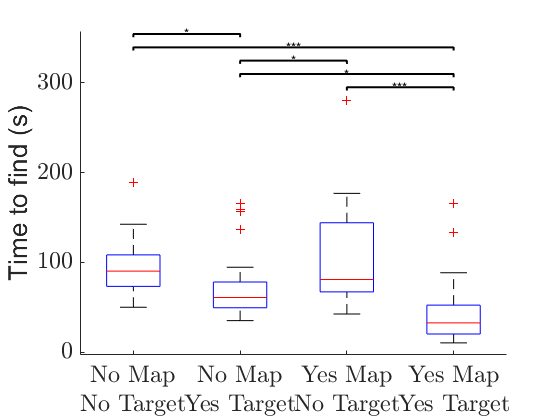

% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} No Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} No Map \\ Yes Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target\end{tabular}'};


%keyboard
% speed
% hyp: speed will depend on prior knowledge.
% higher speeds when target is known (c2 with c1, c4 with c3)
% higher speeds when map is known (c3 with c1)
EKFSpdData = csvread('stats data/RobotSpeedData.csv');
t_EKFSpd = array2table(EKFSpdData,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
EKFSpd_bp = boxplot(table2array(t_EKFSpd(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Robot speed (m/s)')
rm_EKFSpd=fitrm(t_EKFSpd,'C1-C4~1', 'WithinDesign', within);
stats_EKFSpd = ranova(rm_EKFSpd)

stats_EKFSpd = 2×8 table
                              SumSq           DF          MeanSq                  F                  pValue                 pValueGG                pValueHF                pValueLB      
                        __________________    __    ___________________    ________________    ___________________    ____________________    ____________________    ____________________

    (Intercept):cond    0.0419527926011293     3     0.0139842642003764    14.6012975900461    9.7650121284987e-08    4.00280615519143e-07    1.03141077485367e-07    0.000677336196399901
    Error(cond)         0.0804502603681207    84    0.00095774119485858                                    

if stats_EKFSpd.pValue(1) < 0.05
    res_EKFSpd=multcompare(rm_EKFSpd, 'cond', 'ComparisonType','bonferroni')
    sigstar([],res_EKFSpd,1);
end

res_EKFSpd = 12×7 table
    cond_1    cond_2        Difference               StdErr                  pValue                  Lower                  Upper        
    ______    ______    ___________________    ___________________    ____________________    ___________________    ____________________

      1         2       -0.0244946896551724    0.00704310536570148      0.0100198142160778     -0.044489592083631    -0.00449978722671388
      1         3       -0.0136516206896552    0.00641862630907895       0.254266269329546    -0.0318736690775382      0.0045704276982278
      1         4       -0.0517937931034482    0.00845695803250175    7.86218424346639e-06    -0.0758025281601329     -0.0277850580467635
      2         1        0.0244946896551724    

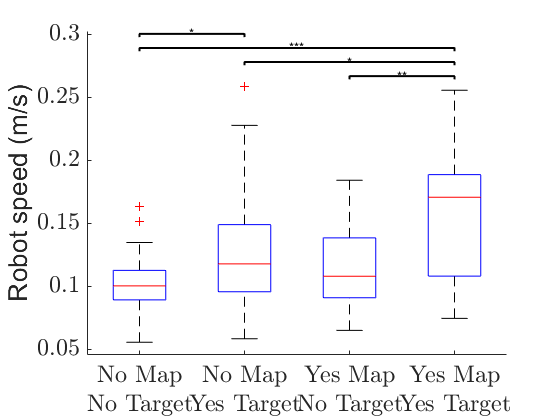

% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} No Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} No Map \\ Yes Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target\end{tabular}'};



% turn rate
% hyp: turn rate will depend on prior knowledge. 
% Higher turn rate when target is not known
% no difference when map is known
EKFOmegaArray = csvread('stats data/RobotTurnrateData.csv');
t_EKFOmega = array2table(EKFOmegaArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
EKFOmega_bp = boxplot(table2array(t_EKFOmega(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Robot turn rate (rad/s)')
rm_EKFOmega=fitrm(t_EKFOmega,'C1-C4~1', 'WithinDesign', within);
stats_EKFOmega = ranova(rm_EKFOmega)

stats_EKFOmega = 2×8 table
                             SumSq          DF         MeanSq                 F                  pValue               pValueGG              pValueHF             pValueLB     
                        ________________    __    _________________    ________________    __________________    __________________    __________________    _________________

    (Intercept):cond    6.09257187553794     3     2.03085729184598    3.29000611618585    0.0245680109356613    0.0360220865867882    0.0314004177688821    0.080434014974022
    Error(cond)         51.8515791432121    84    0.617280704085858                                                                          

if stats_EKFOmega.pValue(1) < 0.05
    res_EKFOmega=multcompare(rm_EKFOmega, 'cond', 'ComparisonType','bonferroni')
    sigstar([],res_EKFOmega,1);
end

res_EKFOmega = 12×7 table
    cond_1    cond_2        Difference             StdErr               pValue                 Lower                 Upper       
    ______    ______    __________________    _________________    _________________    ___________________    __________________

      1         2        0.110767241379311    0.182047955718419                    1     -0.406054660734542     0.627589143493164
      1         3       -0.302990344827586    0.133427584572117    0.186265866854369     -0.681782283363162    0.0758015937079906
      1         4       -0.461285862068965    0.202071377885321    0.181430069007931       -1.0349529129805      0.11238118884257
      2         1       -0.110767241379311    0.182047955718419                    1 

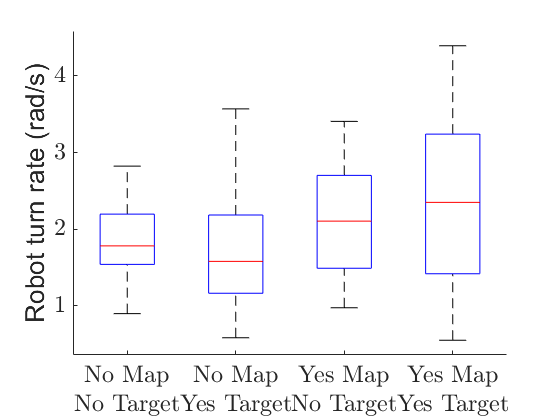

% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} No Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} No Map \\ Yes Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target\end{tabular}'};


% commanded speed
% hyp: commanded speed will depend on prior knowledge. 
% higher speeds when target is known (c2 with c1, c4 with c3)
% higher speeds when map is known (c3 with c1)
comSpeedArray = csvread('stats data/ComSpeedData.csv');
t_comSpeed = array2table(comSpeedArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
comSpeed_bp = boxplot(table2array(t_comSpeed(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Commanded speed (m/s)')
rm_comSpeed=fitrm(t_comSpeed,'C1-C4~1', 'WithinDesign', within);
stats_comSpeed = ranova(rm_comSpeed)

stats_comSpeed = 2×8 table
                              SumSq           DF           MeanSq                  F                   pValue                 pValueGG                pValueHF               pValueLB      
                        __________________    __    ____________________    ________________    ____________________    ____________________    ____________________    ___________________

    (Intercept):cond    0.0279600301394139     3     0.00932001004647129    11.2790251015258    2.72213943800205e-06    1.80522852289861e-05    7.89562929874343e-06    0.00227326339449873
    Error(cond)         0.0694103290715862    84    0.000826313441328407                              

if stats_comSpeed.pValue(1) < 0.05
    res_comSpeed=multcompare(rm_comSpeed, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_comSpeed, 1);
end

res_comSpeed = 12×7 table
    cond_1    cond_2        Difference               StdErr                  pValue                  Lower                   Upper        
    ______    ______    ___________________    ___________________    ____________________    ____________________    ____________________

      1         2       -0.0289549655172414    0.00641167601385221    0.000624175965370445     -0.0471572824844382     -0.0107526485500446
      1         3       -0.0132773103448276    0.00549142859756245       0.134225441754686     -0.0288671067911246      0.0023124861014694
      1         4       -0.0410090344827586    0.00831138813586704    0.000199268954005362      -0.064604506393629     -0.0174135625718883
      2         1        0.0289549655172

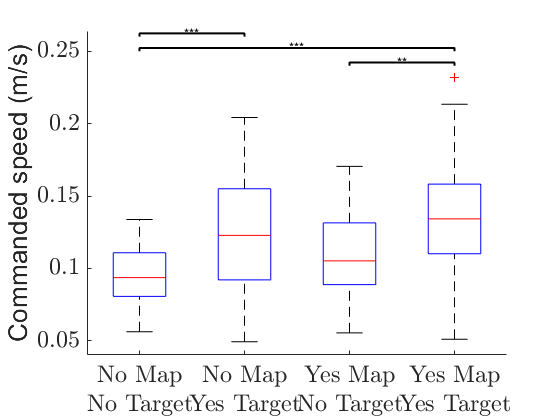

% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} No Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} No Map \\ Yes Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target\end{tabular}'};



% commanded turn rate
% hyp: commanded turn rate will depend on prior knowledge. 
% Higher turn rate when target is not known
% no difference when map is known
comTurnRateArray = csvread('stats data/ComTurnrateData.csv');
t_comTurnRate = array2table(comTurnRateArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
comTurnRate_bp = boxplot(table2array(t_comTurnRate(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Commanded turn rate (rad/s)')
rm_comTurnRate=fitrm(t_comTurnRate,'C1-C4~1', 'WithinDesign', within);
stats_comTurnRate = ranova(rm_comTurnRate)

stats_comTurnRate = 2×8 table
                              SumSq           DF           MeanSq                  F                 pValue                pValueGG                pValueHF                pValueLB      
                        __________________    __    ____________________    ________________    _________________    ____________________    ____________________    ____________________

    (Intercept):cond    0.0399690122011982     3      0.0133230040670661    15.7104802097648    3.39243211872e-08    2.37485386245304e-07    6.14676687816584e-08    0.000463191992842528
    Error(cond)         0.0712347634630517    84    0.000848032898369663                                 

if stats_comTurnRate.pValue(1) < 0.05
    res_comTurnRate=multcompare(rm_comTurnRate, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_comTurnRate,1)
end

res_comTurnRate = 12×7 table
    cond_1    cond_2         Difference               StdErr                  pValue                  Lower                  Upper       
    ______    ______    ____________________    ___________________    ____________________    ___________________    ___________________

      1         2         0.0346732758620689    0.00622242323583454    3.49166770371236e-05      0.017008234802912     0.0523383169212259
      1         3       -0.00603306896551727    0.00771974646188531                       1    -0.0279489099565545       0.01588277202552
      1         4         0.0330138275862069    0.00602247295144684    4.46667129928912e-05     0.0159164319361822     0.0501112232362316
      2         1        -0.03467327586206

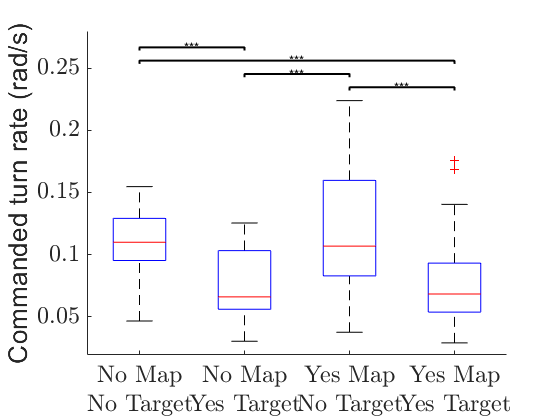

% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} No Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} No Map \\ Yes Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target\end{tabular}'};


% Total distance traveled
TotalDistArray = csvread('stats data/TotalDistanceTravel.csv');
TotalDistArray(:,1)=TotalDistArray(:,1)/2.27;
t_TotalDist = array2table(TotalDistArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
TotalDist_bp = boxplot(table2array(t_TotalDist(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Average total distance traveled (m)')
rm_TotalDist=fitrm(t_TotalDist,'C1-C4~1', 'WithinDesign', within);
stats_TotalDist = ranova(rm_TotalDist)

stats_TotalDist = 2×8 table
                             SumSq          DF         MeanSq                F                   pValue                pValueGG               pValueHF              pValueLB     
                        ________________    __    ________________    ________________    ____________________    ___________________    __________________    __________________

    (Intercept):cond    362.424441030992     3    120.808147010331    6.25226556935666    0.000697223272462352    0.00292583482560558    0.0021891210814882    0.0185316373379733
    Error(cond)         1623.07314625344    84      19.32229936016                                                                 

if stats_TotalDist.pValue(1) < 0.05
    res_TotalDist=multcompare(rm_TotalDist, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_TotalDist,1)
end

res_TotalDist = 12×7 table
    cond_1    cond_2       Difference             StdErr                pValue                 Lower                 Upper       
    ______    ______    _________________    _________________    __________________    ___________________    __________________

      1         2        1.58901040559016    0.773874867165646     0.296938148856067     -0.607968293062649      3.78598910424296
      1         3       -2.00793442199605     1.14232925963882     0.538311946986733      -5.25093035939627      1.23506151540417
      1         4        2.68858281938326     1.04170991784653    0.0923105825885755     -0.268761574118419      5.64592721288494
      2         1       -1.58901040559016    0.773874867165646     0.296938148856067

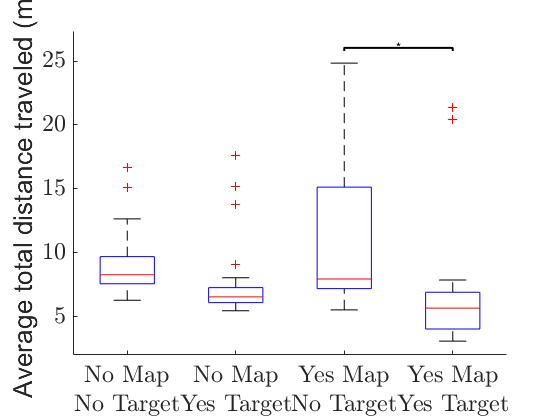

% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} No Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} No Map \\ Yes Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target\end{tabular}'};


% Total time in place traveled
TotalTimeInPlaceArray = csvread('stats data/TotalTimeInPlace.csv');
TotalTimeInPlaceArray(:,1)=TotalTimeInPlaceArray(:,1)/2.27;
t_TotalTimeInPlace = array2table(TotalTimeInPlaceArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
TotalDist_bp = boxplot(table2array(t_TotalTimeInPlace(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Percent time spent turning in place')
rm_TotalTimeInPlace=fitrm(t_TotalTimeInPlace,'C1-C4~1', 'WithinDesign', within);
stats_TotalTimeInPlace = ranova(rm_TotalTimeInPlace)

stats_TotalTimeInPlace = 2×8 table
                             SumSq          DF          MeanSq                 F                   pValue                 pValueGG                pValueHF                pValueLB      
                        ________________    __    __________________    ________________    ____________________    ____________________    ____________________    ____________________

    (Intercept):cond    2.74526598030139     3     0.915088660100463    42.4281617363699    8.63906833277531e-17    4.57729275171409e-10    1.77987523579464e-10    4.64713678428162e-07
    Error(cond)         1.81170817453888    84    0.0215679544587961                                   

if stats_TotalTimeInPlace.pValue(1) < 0.05
    res_TotalTimeInPlace=multcompare(rm_TotalTimeInPlace, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_TotalTimeInPlace,1)
end

res_TotalTimeInPlace = 12×7 table
    cond_1    cond_2         Difference               StdErr                 pValue                  Lower                 Upper       
    ______    ______    ____________________    __________________    ____________________    ___________________    __________________

      1         2         -0.346357419109828    0.0219368644911479    1.07977779428604e-14     -0.408634701971851    -0.284080136247806
      1         3         -0.338744660489139    0.0197342683905308    1.28527919602359e-15     -0.394768921163589    -0.282720399814689
      1         4        -0.0804579708339662    0.0511264537705246       0.760731355815232     -0.225602534428454    0.0646865927605216
      2         1          0.346357419109828   

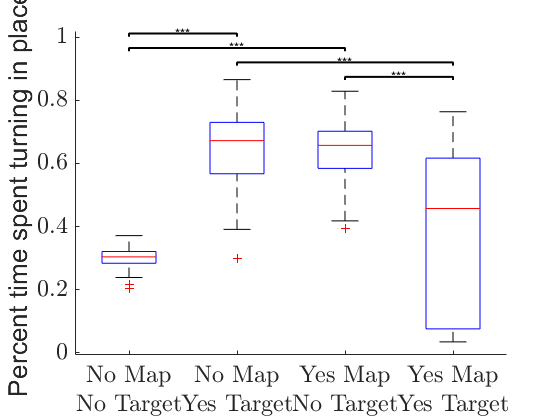

% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} No Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} No Map \\ Yes Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target\end{tabular}'};



% stopping percentage (bearings)
% hyp: stopping percentage will depend on prior knowledge. 
% higher stopping percentage when map is not known
% Total time in place traveled
TotalTimeStoppingArray = csvread('stats data/TotalTimeStopping.csv');
TotalTimeStoppingArray(:,1) = TotalTimeStoppingArray(:,1)/2.27;
t_TotalTimeStoppingArray = array2table(TotalTimeStoppingArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
TotaltimeStopping_bp = boxplot(table2array(t_TotalTimeStoppingArray(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Average time collecting bearing (s)')
rm_TotalTimeStoppingArray=fitrm(t_TotalTimeStoppingArray,'C1-C4~1', 'WithinDesign', within);
stats_TotalTimeStoppingArray = ranova(rm_TotalTimeStoppingArray)

stats_TotalTimeStoppingArray = 2×8 table
                             SumSq          DF         MeanSq                F                   pValue                 pValueGG                pValueHF               pValueLB      
                        ________________    __    ________________    ________________    ____________________    ____________________    ____________________    ___________________

    (Intercept):cond     2589.3981241564     3    863.132708052134    8.87280368159491    3.57052251056028e-05    5.07245976175239e-05    3.57052251056028e-05    0.00592057188848713
    Error(cond)         8171.39092424353    84    97.2784633838515                                        

if stats_TotalTimeStoppingArray.pValue(1) < 0.05
    res_TotalTimeStoppingArray=multcompare(rm_TotalTimeStoppingArray, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_TotalTimeStoppingArray,1)
end

res_TotalTimeStoppingArray = 12×7 table
    cond_1    cond_2       Difference             StdErr               pValue                 Lower                 Upper       
    ______    ______    _________________    ________________    ___________________    __________________    __________________

      1         2         6.2187452529242    2.25638175999305     0.0610425525248753    -0.186970804103882      12.6244613099523
      1         3       -2.14332371259304    2.78518774280592                      1      -10.050284388425      5.76363696323896
      1         4        9.64977973568281    2.54321972412825    0.00436430158388241      2.42974999060589      16.8698094807597
      2         1        -6.2187452529242    2.25638175999305     0.06104255

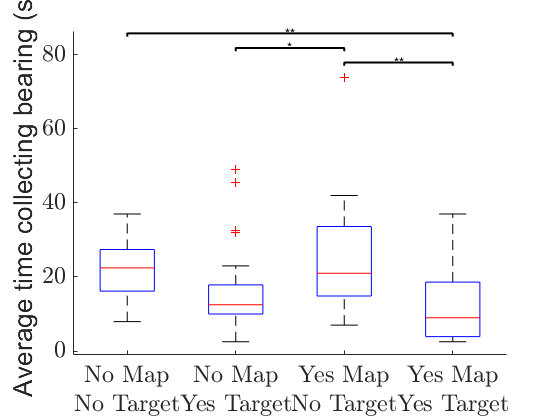

% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} No Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} No Map \\ Yes Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target\end{tabular}'};


TotalPercentStoppingArray = csvread('stats data/TotalPercentStopping.csv');
t_TotalPercentStoppingArray = array2table(TotalPercentStoppingArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
Totalpercentstopping_bp = boxplot(table2array(t_TotalPercentStoppingArray(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Percent time spent in place')
rm_TotalPercentStoppingArray=fitrm(t_TotalPercentStoppingArray,'C1-C4~1', 'WithinDesign', within);
stats_TotalPercentStoppingArray = ranova(rm_TotalPercentStoppingArray)

stats_TotalPercentStoppingArray = 2×8 table
                              SumSq          DF          MeanSq                  F                  pValue                pValueGG               pValueHF               pValueLB     
                        _________________    __    ___________________    _______________    ____________________    ___________________    ___________________    __________________

    (Intercept):cond    0.114828852512715     3     0.0382762841709051    7.3296033521236    0.000201078297491571    0.00189807774366654    0.00145762680962255    0.0114280197261676
    Error(cond)         0.438660554452035    84    0.00522214945776232                                 

if stats_TotalPercentStoppingArray.pValue(1) < 0.05
    res_TotalPercentStoppingArray=multcompare(rm_TotalPercentStoppingArray, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_TotalPercentStoppingArray,1)
end

res_TotalPercentStoppingArray = 12×7 table
    cond_1    cond_2         Difference               StdErr                pValue                  Lower                   Upper        
    ______    ______    ____________________    __________________    ___________________    ____________________    ____________________

      1         2         0.0142303448275862    0.0135077077474978                      1      -0.024117128966944      0.0525778186221164
      1         3       -0.00941275862068966    0.0107304394028146                      1     -0.0398757543780157      0.0210502371366364
      1         4         0.0716177586206896    0.0248105633045047      0.044532343277264     0.00118223810661355       0.142053279134766
      2         1        -0.

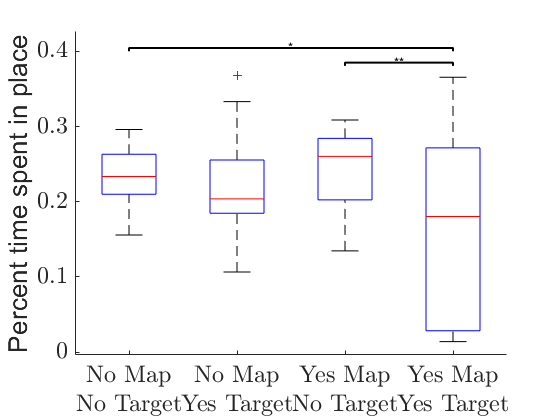

% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} No Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} No Map \\ Yes Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target\end{tabular}'};



% ------------------------------------------------------------
% -- looking at only conditions 3, 4a, and 4b

% speed between 3, 4a and 4b
% knowledge of the target not present in location 1 implies it's presence in location 2, 
% thus leading to an increase in speed which resembles when target location is known in 4a
EKFSpdData = csvread('stats data/RobotSpeedData.csv');
EKFSpdData = EKFSpdData(EKFSpdData(:,5)~=0,[3,4,5]);
t_EKFSpd = array2table(EKFSpdData,...
    'VariableNames',{'C1','C2','C3'});
EKFSpd_bp = boxplot(table2array(t_EKFSpd(:,1:3)), 'labels', {'C3','C4', 'C5'});
ylabel('Speed prior knowledge accuracy (m/s)')
within3=array2table([1 2 3]', 'variablenames', {'cond'});
rm_EKFSpd=fitrm(t_EKFSpd,'C1-C3~1', 'WithinDesign', within3);
stats_EKFSpd = ranova(rm_EKFSpd)

stats_EKFSpd = 2×8 table
                            SumSq         DF          MeanSq                  F                  pValue                pValueGG              pValueHF               pValueLB     
                        ______________    __    ___________________    ________________    ___________________    __________________    ___________________    __________________

    (Intercept):cond    0.016163940979     2    0.00808197048950001    6.69070481911775    0.00452759088501177    0.0056152450022151    0.00452759088501177    0.0225707406426949
    Error(cond)         0.031406441983    26    0.00120794007626923                                                                   

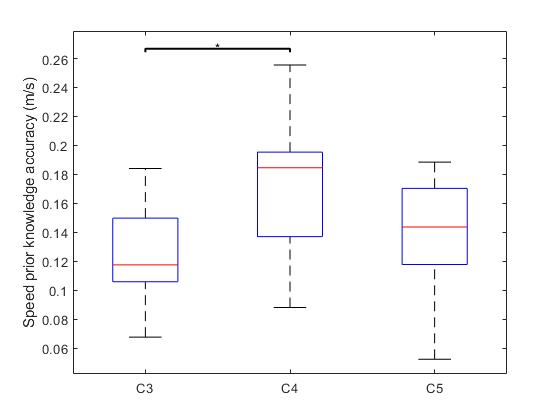

res_EKFSpd = 6×7 table
    cond_1    cond_2        Difference               StdErr                pValue                 Lower                   Upper        
    ______    ______    ___________________    __________________    __________________    ____________________    ____________________

      1         2       -0.0467398571428571    0.0140873549587811    0.0166608063149162     -0.0854228706312511    -0.00805684365446312
      1         3       -0.0137060714285714    0.0112316146963124     0.732063447052459     -0.0445473971469297      0.0171352542897869
      2         1        0.0467398571428571    0.0140873549587811    0.0166608063149162     0.00805684365446312      0.0854228706312511
      2         3        0.0330337857142857    0.013895534

if stats_EKFSpd.pValue(1) < 0.05
    res_EKFSpd=multcompare(rm_EKFSpd, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_EKFSpd,1)
end

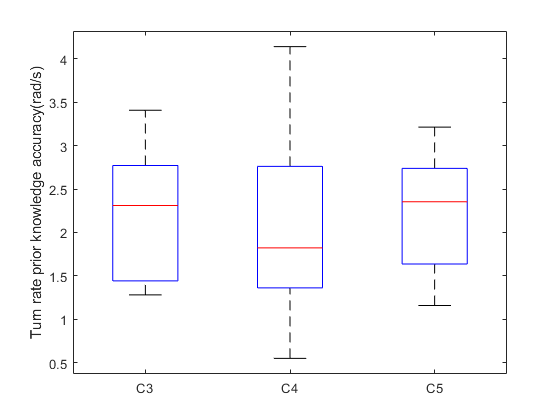


EKFOmegaArray = csvread('stats data/RobotTurnrateData.csv');
EKFOmegaArray = EKFOmegaArray((EKFOmegaArray(:,5) ~= 0), [3,4,5]);
t_EKFOmega = array2table(EKFOmegaArray,...
    'VariableNames',{'C1','C2','C3'});
EKFOmega_bp = boxplot(table2array(t_EKFOmega(:,1:3)), 'labels', {'C3','C4','C5'});
ylabel('Turn rate prior knowledge accuracy(rad/s)')

rm_EKFOmega=fitrm(t_EKFOmega,'C1-C3~1', 'WithinDesign', within3);
stats_EKFOmega = ranova(rm_EKFOmega)

stats_EKFOmega = 2×8 table
                              SumSq          DF         MeanSq                 F                pValue              pValueGG             pValueHF             pValueLB     
                        _________________    __    _________________    _______________    _________________    _________________    _________________    _________________

    (Intercept):cond    0.309372968290473     2    0.154686484145237    0.1743446230753    0.840981267997927    0.748204182741624    0.763371524007723    0.683092881036835
    Error(cond)          23.0683832792429    26     0.88724551074011                                                                                  

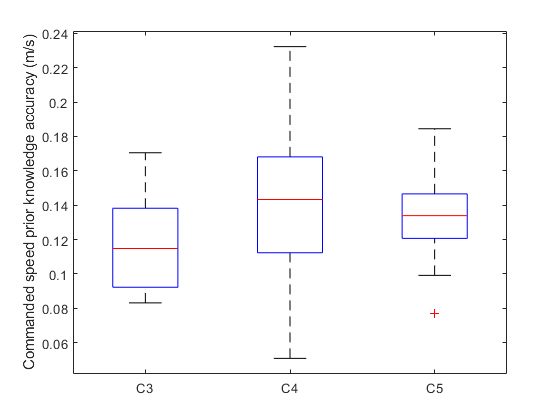

if stats_EKFOmega.pValue(1) < 0.05
    res_EKFOmega=multcompare(rm_EKFOmega, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_EKFOmega,1)
end

% commanded speed
% hyp: commanded speed will depend on prior knowledge. 
% higher speeds when target is known (c2 with c1, c4 with c3)
% higher speeds when map is known (c3 with c1)
comSpeedArray = csvread('stats data/ComSpeedData.csv');
comSpeedArray = comSpeedArray((comSpeedArray(:,5) ~= 0), [3,4,5]);
t_comSpeed = array2table(comSpeedArray,...
    'VariableNames',{'C1','C2','C3'});
comSpeed_bp = boxplot(table2array(t_comSpeed(:,1:3)), 'labels', {'C3','C4','C5'});
ylabel('Commanded speed prior knowledge accuracy (m/s)')

rm_comSpeed=fitrm(t_comSpeed,'C1-C3~1', 'WithinDesign', within3);
stats_comSpeed = ranova(rm_comSpeed)

stats_comSpeed = 2×8 table
                               SumSq           DF           MeanSq                  F                 pValue              pValueGG             pValueHF            pValueLB     
                        ___________________    __    ____________________    ________________    _________________    _________________    ________________    _________________

    (Intercept):cond    0.00435950857490477     2     0.00217975428745238    2.25681743355656    0.124805072758879    0.140693933941896    0.13558133160843    0.156923789729404
    Error(cond)          0.0251121825944286    26    0.000965853176708791                                                              

if stats_comSpeed.pValue(1) < 0.05
    res_comSpeed=multcompare(rm_comSpeed, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_comSpeed, 1);
end


% commanded turn rate
% hyp: commanded turn rate will depend on prior knowledge. 
% Higher turn rate when target is not known
% no difference when map is known
comTurnRateArray = csvread('stats data/ComTurnrateData.csv');
comTurnRateArray = comTurnRateArray((comTurnRateArray(:,5) ~= 0), [3,4,5]);
t_comTurnRate = array2table(comTurnRateArray,...
    'VariableNames',{'C1','C2','C3'});
comTurnRate_bp = boxplot(table2array(t_comTurnRate(:,1:3)), 'labels', {'C3','C4','C5'});
ylabel('Commanded turn rate prior knowledge accuracy (rad/s)')
rm_comTurnRate=fitrm(t_comTurnRate,'C1-C3~1', 'WithinDesign', within3);
stats_comTurnRate = ranova(rm_comTurnRate)

stats_comTurnRate = 2×8 table
                              SumSq           DF          MeanSq                  F                  pValue                pValueGG              pValueHF               pValueLB     
                        __________________    __    ___________________    ________________    ___________________    __________________    ___________________    __________________

    (Intercept):cond    0.0242030253264762     2     0.0121015126632381    5.97070615816707    0.00734815174792848    0.0111248237713945    0.00810503601791072    0.0295717367543307
    Error(cond)         0.0526971719775238    26    0.00202681430682784                                              

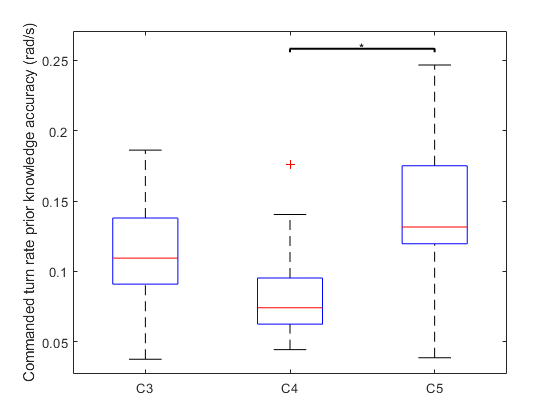

res_comTurnRate = 6×7 table
    cond_1    cond_2        Difference               StdErr                pValue                 Lower                  Upper        
    ______    ______    ___________________    __________________    __________________    ___________________    ____________________

      1         2        0.0294225714285714    0.0146486351000209     0.197471220263923    -0.0108016829342007      0.0696468257913436
      1         3       -0.0293785714285714     0.015620443200405     0.247770118475717    -0.0722713512856812      0.0135142084285384
      2         1       -0.0294225714285714    0.0146486351000209     0.197471220263923    -0.0696468257913436      0.0108016829342007
      2         3       -0.0588011428571428    0.020249788

if stats_comTurnRate.pValue(1) < 0.05
    res_comTurnRate=multcompare(rm_comTurnRate, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_comTurnRate,1)
end




% NASA TLX
% all stats
% -- Questions that were on the NASA TLX with the corresponding value bar range
% -- Q1) Mental demand: Low - High
% -- Q2) Physical demand: Low - High
% -- Q3) Temporal demand: Low - High
% -- Q4) Performance: Perfect - Failure
% -- Q5) Effort: Low - High
% -- Q6) Frustration: Low - High

NASATLXArrayQ1 = csvread('stats data/TLX_question_1.csv');
t_NASATLXQ1 = array2table(NASATLXArrayQ1,...
    'VariableNames',{'C1','C2','C3','C4'});
NASATLXQ1_bp = boxplot(table2array(t_NASATLXQ1), 'labels', {'C1','C2','C3','C4'});
ylabel('Question response for Q1')
within2=array2table([1 2 3 4]', 'variablenames', {'cond'});
rm_NASATLXQ1=fitrm(t_NASATLXQ1,'C1-C4~1', 'WithinDesign', within2);
stats_NASATLXQ1 = ranova(rm_NASATLXQ1)

stats_NASATLXQ1 = 2×8 table
                             SumSq          DF         MeanSq                F                  pValue               pValueGG              pValueHF             pValueLB     
                        ________________    __    ________________    ________________    __________________    __________________    __________________    _________________

    (Intercept):cond    2294.82758620689     3    764.942528735631    4.19141877073609    0.0081525844958312    0.0106106601287441    0.0081525844958312    0.050116185412239
    Error(cond)         15330.1724137931    84    182.502052545156                                                                             

if stats_NASATLXQ1.pValue(1) < 0.05
    res_NASATLXQ1=multcompare(rm_NASATLXQ1, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_NASATLXQ1,1)
end

res_NASATLXQ1 = 12×7 table
    cond_1    cond_2       Difference             StdErr               pValue                Lower                 Upper       
    ______    ______    _________________    ________________    __________________    __________________    __________________

      1         2        11.3793103448276    4.25406609118107    0.0740409026866972    -0.697697168307604      23.4563178579628
      1         3        9.48275862068965    3.29524986145163    0.0455062165915546     0.127765895750558      18.8377513456288
      1         4        9.48275862068965    3.69182984575239    0.0950011045223802    -0.998098006525963      19.9636152479053
      2         1       -11.3793103448276    4.25406609118107    0.0740409026866972     -23.45

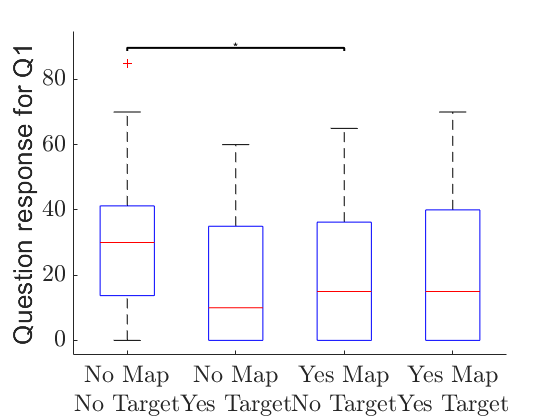

% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} No Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} No Map \\ Yes Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target\end{tabular}'};


NASATLXArrayQ2 = csvread('stats data/TLX_question_2.csv');
t_NASATLXQ2 = array2table(NASATLXArrayQ2,...
    'VariableNames',{'C1','C2','C3','C4'});
NASATLXQ2_bp = boxplot(table2array(t_NASATLXQ2), 'labels', {'C1','C2','C3','C4'});
ylabel('Question response for Q2')
within2=array2table([1 2 3 4]', 'variablenames', {'cond'});
rm_NASATLXQ2=fitrm(t_NASATLXQ2,'C1-C4~1', 'WithinDesign', within2);
stats_NASATLXQ2 = ranova(rm_NASATLXQ2)

stats_NASATLXQ2 = 2×8 table
                             SumSq          DF         MeanSq                F                  pValue                pValueGG              pValueHF              pValueLB     
                        ________________    __    ________________    ________________    ___________________    __________________    __________________    __________________

    (Intercept):cond    1510.99137931034     3    503.663793103447    4.13959765509679    0.00868315788943203    0.0178226688117488    0.0150189304408125    0.0514600463646813
    Error(cond)         10220.2586206897    84    121.669745484401                                                                       

if stats_NASATLXQ2.pValue(1) < 0.05
    res_NASATLXQ2=multcompare(rm_NASATLXQ2, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_NASATLXQ2,1)
end

res_NASATLXQ2 = 12×7 table
    cond_1    cond_2         Difference               StdErr               pValue                Lower                 Upper      
    ______    ______    _____________________    ________________    __________________    __________________    _________________

      1         2            8.79310344827586    3.48867954975078      0.10618751276758      -1.1110231520619     18.6972300486136
      1         3                           5    2.43132269541932     0.294971799091466     -1.90236160653609     11.9023616065361
      1         4            8.79310344827586    3.39928249106356    0.0910675000835239    -0.857230915111014     18.4434378116627
      2         1           -8.79310344827586    3.48867954975078      0.106187

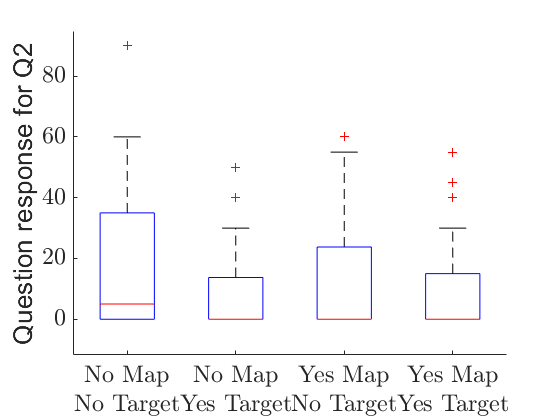

% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} No Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} No Map \\ Yes Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target\end{tabular}'};


NASATLXArrayQ3 = csvread('stats data/TLX_question_3.csv');
t_NASATLXQ3 = array2table(NASATLXArrayQ3,...
    'VariableNames',{'C1','C2','C3','C4'});
NASATLXQ3_bp = boxplot(table2array(t_NASATLXQ3), 'labels', {'C1','C2','C3','C4'});
ylabel('Question response for Q3')
within2=array2table([1 2 3 4]', 'variablenames', {'cond'});
rm_NASATLXQ3=fitrm(t_NASATLXQ3,'C1-C4~1', 'WithinDesign', within2);
stats_NASATLXQ3 = ranova(rm_NASATLXQ3)

stats_NASATLXQ3 = 2×8 table
                             SumSq          DF         MeanSq                F                 pValue              pValueGG             pValueHF             pValueLB     
                        ________________    __    ________________    ________________    _________________    _________________    _________________    _________________

    (Intercept):cond    1242.24137931034     3    414.080459770114    1.92619468181601    0.131554730462151    0.147499835334198    0.142191287724192    0.176121379806444
    Error(cond)         18057.7586206897    84    214.973316912972                                                                                      

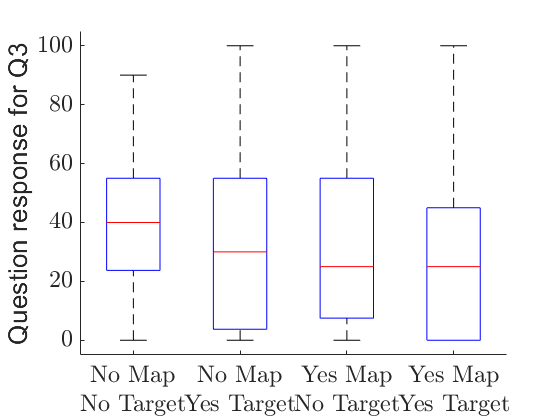

if stats_NASATLXQ3.pValue(1) < 0.05
    res_NASATLXQ3=multcompare(rm_NASATLXQ3, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_NASATLXQ3,1)
end
% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} No Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} No Map \\ Yes Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target\end{tabular}'};


NASATLXArrayQ4 = csvread('stats data/TLX_question_4.csv');
t_NASATLXQ4 = array2table(NASATLXArrayQ4,...
    'VariableNames',{'C1','C2','C3','C4'});
NASATLXQ4_bp = boxplot(table2array(t_NASATLXQ4), 'labels', {'C1','C2','C3','C4'});
ylabel('Question response for Q4')
within2=array2table([1 2 3 4]', 'variablenames', {'cond'});
rm_NASATLXQ4=fitrm(t_NASATLXQ4,'C1-C4~1', 'WithinDesign', within2);
stats_NASATLXQ4 = ranova(rm_NASATLXQ4)

stats_NASATLXQ4 = 2×8 table
                             SumSq          DF         MeanSq                 F                 pValue              pValueGG             pValueHF             pValueLB     
                        ________________    __    ________________    _________________    _________________    _________________    _________________    _________________

    (Intercept):cond    255.172413793103     3    85.0574712643678    0.870542513523449    0.459765220151738    0.413787389067677    0.419358342119717    0.358781691159739
    Error(cond)          8207.3275862069    84    97.7062807881774                                                                                   

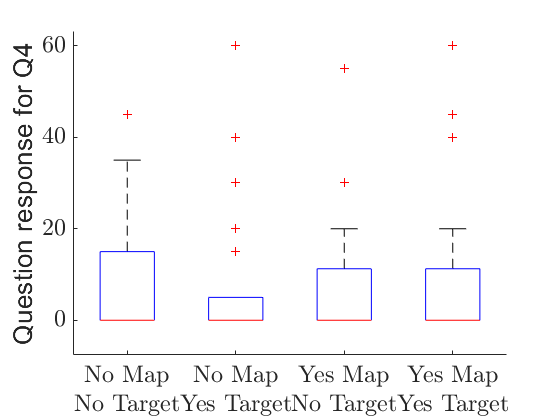

if stats_NASATLXQ4.pValue(1) < 0.05
    res_NASATLXQ4=multcompare(rm_NASATLXQ4, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_NASATLXQ4,1)
end
% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} No Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} No Map \\ Yes Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target\end{tabular}'};


NASATLXArrayQ5 = csvread('stats data/TLX_question_5.csv');
t_NASATLXQ5 = array2table(NASATLXArrayQ5,...
    'VariableNames',{'C1','C2','C3','C4'});
NASATLXQ5_bp = boxplot(table2array(t_NASATLXQ5), 'labels', {'C1','C2','C3','C4'});
ylabel('Question response for Q5')
within2=array2table([1 2 3 4]', 'variablenames', {'cond'});
rm_NASATLXQ5=fitrm(t_NASATLXQ5,'C1-C4~1', 'WithinDesign', within2);
stats_NASATLXQ5 = ranova(rm_NASATLXQ5)

stats_NASATLXQ5 = 2×8 table
                             SumSq          DF         MeanSq                F                  pValue                pValueGG               pValueHF              pValueLB     
                        ________________    __    ________________    ________________    ___________________    ___________________    ___________________    _________________

    (Intercept):cond    4352.37068965516     3    1450.79022988505    5.85786802030455    0.00110740827187948    0.00194663833150159    0.00125917753725607    0.022245836530795
    Error(cond)         20803.8793103448    84    247.665229885058                                                                    

if stats_NASATLXQ5.pValue(1) < 0.05
    res_NASATLXQ5=multcompare(rm_NASATLXQ5, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_NASATLXQ5,1)
end

res_NASATLXQ5 = 12×7 table
    cond_1    cond_2        Difference             StdErr               pValue                 Lower                Upper      
    ______    ______    __________________    ________________    ___________________    _________________    _________________

      1         2         14.8275862068965    3.80790885733968    0.00334858946526512     4.01718907301996     25.6379833407731
      1         3         15.1724137931034    3.69297994853598     0.0018838335510125     4.68829210143877     25.6565354847681
      1         4         9.82758620689655    4.69174649109923      0.272236795156784    -3.49196652412362     23.1471389379167
      2         1        -14.8275862068965    3.80790885733968    0.00334858946526512    -25.6

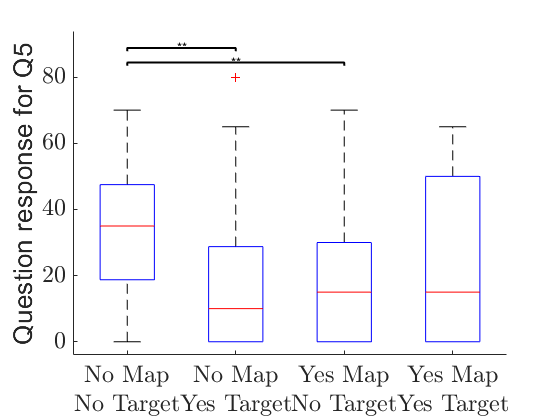

% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} No Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} No Map \\ Yes Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target\end{tabular}'};


NASATLXArrayQ6 = csvread('stats data/TLX_question_6.csv');
t_NASATLXQ6 = array2table(NASATLXArrayQ6,...
    'VariableNames',{'C1','C2','C3','C4'});
NASATLXQ6_bp = boxplot(table2array(t_NASATLXQ6), 'labels', {'C1','C2','C3','C4'});
ylabel('Question response for Q6')
within2=array2table([1 2 3 4]', 'variablenames', {'cond'});
rm_NASATLXQ6=fitrm(t_NASATLXQ6,'C1-C4~1', 'WithinDesign', within2);
stats_NASATLXQ6 = ranova(rm_NASATLXQ6)

stats_NASATLXQ6 = 2×8 table
                             SumSq          DF         MeanSq                F                  pValue               pValueGG              pValueHF             pValueLB     
                        ________________    __    ________________    ________________    __________________    __________________    __________________    _________________

    (Intercept):cond    2085.12931034483     3    695.043103448275    2.88547569340888    0.0404336418555569    0.0599327631474074    0.0550355268567796    0.100468679871448
    Error(cond)         20233.6206896552    84    240.876436781609                                                                             

if stats_NASATLXQ6.pValue(1) < 0.05
    res_NASATLXQ6=multcompare(rm_NASATLXQ6, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_NASATLXQ6,1)
end

res_NASATLXQ6 = 12×7 table
    cond_1    cond_2       Difference             StdErr               pValue                 Lower                 Upper       
    ______    ______    _________________    ________________    __________________    ___________________    __________________

      1         2        10.6896551724138    3.79366319201805    0.0526265703162452    -0.0802994757487934      21.4596098205764
      1         3         5.6896551724138    2.92269169087184     0.369986087623833      -2.60766996374489      13.9869803085725
      1         4         1.0344827586207    5.13595525207166                     1      -13.5461487682334      15.6151142854748
      2         1       -10.6896551724138    3.79366319201805    0.0526265703162452      

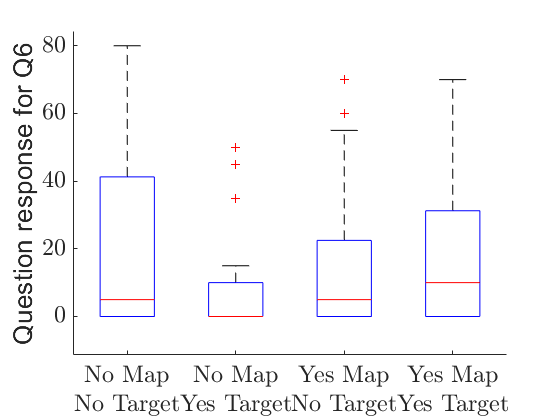

% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} No Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} No Map \\ Yes Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target\end{tabular}'};


% -- commanded acceleration
ComAccelArray = csvread('stats data/CommandedAccel.csv');
t_ComAccelArray = array2table(ComAccelArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
ComAccelArray_bp = boxplot(table2array(t_ComAccelArray(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Commanded Acceleration (m/s)')
rm_ComAccelArray=fitrm(t_ComAccelArray,'C1-C4~1', 'WithinDesign', within);
stats_ComAccelArray = ranova(rm_ComAccelArray)

stats_ComAccelArray = 2×8 table
                               SumSq           DF           MeanSq                  F                   pValue                 pValueGG               pValueHF               pValueLB      
                        ___________________    __    ____________________    ________________    ____________________    ____________________    ___________________    ___________________

    (Intercept):cond    0.00177702507831453     3    0.000592341692771509    13.0166346513237    4.62912913901144e-07    0.000792027462596279    0.00075578038681043    0.00118951866021211
    Error(cond)         0.00382254734235372    84    4.55065159804014e-05                        

if stats_ComAccelArray.pValue(1) < 0.05
    res_ComAccelArray=multcompare(rm_ComAccelArray, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_ComAccelArray,1)
end

res_ComAccelArray = 12×7 table
    cond_1    cond_2         Difference                 StdErr                 pValue                   Lower                   Upper        
    ______    ______    _____________________    ____________________    ___________________    _____________________    ____________________

      1         2        5.19923689655172e-05    0.000423030854365846                      1     -0.00114896377439471     0.00125294851232574
      1         3         0.00121848361724138    0.000453668516470748     0.0721522552984565    -6.94507882085802e-05     0.00250641802269134
      1         4         -0.0085451465275862     0.00246742330235095     0.0104076806319417      -0.0155499953291487    -0.00154029772602372
      2         1   

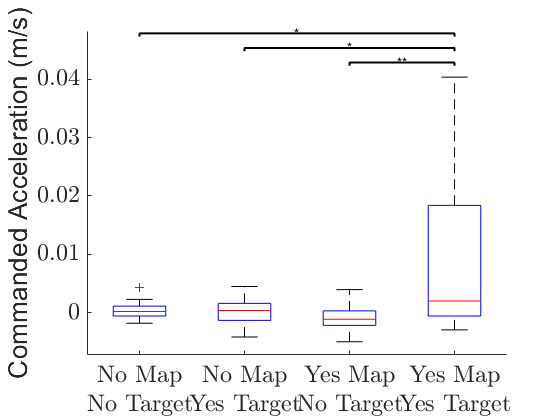

% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} No Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} No Map \\ Yes Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target\end{tabular}'};



% Total time in place traveled
TotalTimeInPlaceArray = csvread('stats data/TotalTimeInPlace.csv');
TotalTimeInPlaceArray(:,1)=TotalTimeInPlaceArray(:,1)/2.27;
TotalTimeInPlaceArray = TotalTimeInPlaceArray((TotalTimeInPlaceArray(:,5) ~= 0), [3,4,5]);
t_TotalTimeInPlace = array2table(TotalTimeInPlaceArray,...
    'VariableNames',{'C1','C2','C3'});
TotalDist_bp = boxplot(table2array(t_TotalTimeInPlace(:,1:3)), 'labels', {'C1','C2','C3'});
ylabel('Percent time spent turning in place')
rm_TotalTimeInPlace=fitrm(t_TotalTimeInPlace,'C1-C3~1', 'WithinDesign', within3);
stats_TotalTimeInPlace = ranova(rm_TotalTimeInPlace)

stats_TotalTimeInPlace = 2×8 table
                              SumSq          DF          MeanSq                 F                   pValue                 pValueGG                pValueHF                pValueLB      
                        _________________    __    __________________    ________________    ____________________    ____________________    ____________________    ____________________

    (Intercept):cond     1.56799961974933     2     0.783999809874666    31.8404535619686    1.02224176596562e-07    4.37432358409457e-06    1.85275391953206e-06    8.02701011377333e-05
    Error(cond)         0.640191730217333    26    0.0246227588545128                               

if stats_TotalTimeInPlace.pValue(1) < 0.05
    res_TotalTimeInPlace=multcompare(rm_TotalTimeInPlace, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_TotalTimeInPlace,1)
end

res_TotalTimeInPlace = 6×7 table
    cond_1    cond_2        Difference              StdErr                 pValue                  Lower                    Upper        
    ______    ______    __________________    __________________    ____________________    ____________________    _____________________

      1         2        0.464077428571429    0.0435665362700352    2.58097951000896e-07       0.344446389593037         0.58370846754982
      1         3        0.151577142857143    0.0550100228173109      0.0490999127203482    0.000522991040482534        0.302631294673803
      2         1       -0.464077428571429    0.0435665362700352    2.58097951000896e-07       -0.58370846754982       -0.344446389593037
      2         3       -0.31250028571

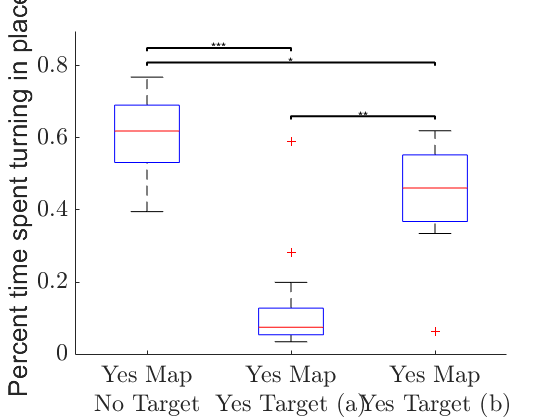

% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target (a)\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target (b)\end{tabular}'};


TotalPercentStoppingArray = csvread('stats data/TotalPercentStopping.csv');
TotalPercentStoppingArray = TotalPercentStoppingArray((TotalPercentStoppingArray(:,5) ~= 0), [3,4,5]);
t_TotalPercentStoppingArray = array2table(TotalPercentStoppingArray,...
    'VariableNames',{'C1','C2','C3'});
Totalpercentstopping_bp = boxplot(table2array(t_TotalPercentStoppingArray(:,1:3)), 'labels', {'C1','C2','C3'});
ylabel('Percent time spent in place')
rm_TotalPercentStoppingArray=fitrm(t_TotalPercentStoppingArray,'C1-C3~1', 'WithinDesign', within3);
stats_TotalPercentStoppingArray = ranova(rm_TotalPercentStoppingArray)

stats_TotalPercentStoppingArray = 2×8 table
                              SumSq           DF          MeanSq                  F                   pValue                 pValueGG                pValueHF                pValueLB      
                        __________________    __    ___________________    ________________    ____________________    ____________________    ____________________    ____________________

    (Intercept):cond     0.265221246802904     2      0.132610623401452    38.5564268700085    1.66566261759977e-08    7.95339945609701e-07    2.62233394784017e-07    3.17091246555677e-05
    Error(cond)         0.0894241631897619    26    0.00343939089191392              

if stats_TotalPercentStoppingArray.pValue(1) < 0.05
    res_TotalPercentStoppingArray=multcompare(rm_TotalPercentStoppingArray, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_TotalPercentStoppingArray,1)
end

res_TotalPercentStoppingArray = 6×7 table
    cond_1    cond_2        Difference               StdErr                 pValue                  Lower                   Upper       
    ______    ______    ___________________    __________________    ____________________    ____________________    ___________________

      1         2         0.188336785714286    0.0155300489884733    5.52363681387067e-08        0.14569222282407      0.230981348604501
      1         3        0.0515831428571429    0.0221622540505885       0.110195350454554    -0.00927304873315608      0.112439334447442
      2         1        -0.188336785714286    0.0155300489884733    5.52363681387067e-08      -0.230981348604501      -0.14569222282407
      2         3        -0.136753

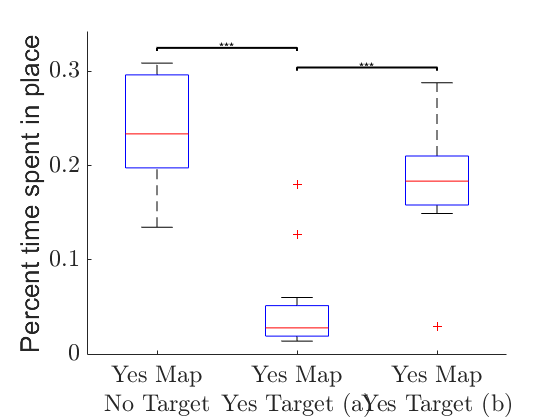

% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target (a)\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target (b)\end{tabular}'};


% post trial


% we place target in a different location in 4b to see the change in behavior
% when the participant realizes that their prior knowledge is inaccurate
% we compared the actions between condition 3, when they did not have any knowledge
% of target location and condition 4b, when they again don't have knowledge about target location
% but thought they did
% 3 and 4b


% 
% % -- display all tables that contain the data from the input, tracker and
% % -- the questionnaires
% % t_time
% % t_Vel
% % t_EKFSpd
% % t_Omega
% % t_EKFOmega
% % t_TotalTimeInPlace
% % t_TotalTimeStoppingArray
% % t_TotalPercentStoppingArray
% % t_NASATLX
% % t_ComAccelArray
% 
% % -- create box plots for each of the tables, solely looking at conditions 1-4
% % -- all at the same time
% 
% 
% 
% 
% % -- apply the within to the data to get the rm
% % -- for right now solely look at conditions 1-4 without the questions
% 
% 
% % -- display the repeated measures for all data
% rm_time
% rm_Vel
% rm_EKFSpd
% rm_Omega
% rm_EKFOmega
% rm_TotalTimeInPlace
% rm_TotalTimeStoppingArray
% rm_TotalPercentStoppingArray
% rm_NASATLX
% rm_ComAccelArray
% 
% % -- after running the fit rm function, run the stats function and display it
% 
% 
% % -- check if the stats p value is below 0.05, if it is, display the
% % -- pairwise comparisons
% 




% 